## Modelado de sistema final

Para la pieza


$$\begin{array}{l}
C_p \;\frac{{\textrm{dT}}_p }{\textrm{dt}}=Q_{w\longrightarrow p} +Q_{a\longrightarrow p} \longrightarrow C_p \frac{T_p^{i+1} -T_p^i }{\Delta t}=\varepsilon_p \sigma A_p \left(T_w^4 -T_p^4 \right)+h_{\textrm{aip}} A_p \left(T_a -T_p \right)\\
T_p^{i+1} =T_p^i +\frac{\varepsilon_p \sigma A_p \Delta t}{C_p }\left({T_w^4 }^i -{T_p^4 }^i \right)+\frac{h_{\textrm{aip}} A_p \Delta t}{C_p }\left(T_w^i -T_p^i \right)
\end{array}$$


Para el aire


$$\begin{array}{l}
C_a \;\frac{{\textrm{dT}}_a }{\textrm{dt}}=Q_{w\longrightarrow a} -Q_{p\longrightarrow a} \longrightarrow C_a \frac{T_a^{i+1} -T_a^i }{\Delta t}=h_{\textrm{aiw}} A_w \left(T_w -T_a \right)-h_{\textrm{aip}} A_p \left(T_a -T_p \right)\\
T_a^{i+1} =T_a^i +\frac{h_{\textrm{aiw}} A_w \Delta t}{C_a }\left(T_w^i -T_a^i \right)-\frac{h_{\textrm{aip}} A_p \Delta t}{C_a }\left(T_a^i -T_p^i \right)
\end{array}$$


Para la pared


$$\begin{array}{l}
C_w \;\frac{{\textrm{dT}}_w }{\textrm{dt}}=Q_{\textrm{in}} -Q_{w\longrightarrow a} -Q_{w\longrightarrow p} -Q_{w\longrightarrow e} \longrightarrow C_w \;\frac{T_w^{i+1} -T_w^i }{\Delta t}=Q_{\textrm{in}} -h_{\textrm{aiw}} A_w \left(T_w -T_a \right)-\varepsilon_p \sigma A_p \left(T_w^4 -T_p^4 \right)-\frac{\left(T_w -T_f \right)}{R_{i\longrightarrow f} }\\
T_w^{i+1} =T_w^i -\frac{\Delta t}{C_w }\;Q_{\textrm{in}} -\frac{h_{\textrm{aiw}} A_w \Delta t}{C_w }\left(T_w^i -T_a^i \right)-\frac{\varepsilon_p \sigma A_p \Delta t}{C_w }\left({T_w^4 }^i -{T_p^4 }^i \right)-\frac{\Delta t}{C_w R_{i\longrightarrow e} }\left(T_w^i -T_e \right)
\end{array}$$


A partir de aca, añadiremos ecuaciones representantes de cada nodo

Para el nodo de la fibra


$$\begin{array}{l}
C_f \;\frac{{\textrm{dT}}_f }{\textrm{dt}}=\frac{\left(T_w -T_f \right)}{R_{i\longrightarrow f} }-\frac{\left(T_f -T_{\textrm{la}} \right)}{R_{f\longrightarrow e} }\longrightarrow C_f \;\frac{T_f^{i+1} -T_f^i }{\Delta t}=\frac{\left(T_w -T_f \right)}{R_{i\longrightarrow f} }-\frac{\left(T_f -T_{\textrm{la}} \right)}{R_{f\longrightarrow e} }\\
T_f^{i+1} =T_f^i +\frac{\Delta t}{C_f R_{i\longrightarrow f} }\left(T_w^i -T_f^i \right)-\frac{\Delta t}{C_f R_{f\longrightarrow e} }\left(T_f -T_{\textrm{la}} \right)
\end{array}$$


Para el nodo de la lana 1


$$\begin{array}{l}
C_{\textrm{la}} \;\frac{{\textrm{dT}}_{\textrm{la}} }{\textrm{dt}}=\frac{\left(T_f -T_{\textrm{la}} \right)}{R_{f\longrightarrow \textrm{la}} }-\frac{\left(T_{\textrm{la}} -T_{\textrm{lb}} \right)}{R_{\textrm{la}\longrightarrow \textrm{lb}} }\longrightarrow C_{\textrm{la}} \;\frac{T_{\textrm{la}}^{i+1} -T_{\textrm{la}}^i }{\Delta t}=\frac{\left(T_f -T_{\textrm{la}} \right)}{R_{f\longrightarrow \textrm{la}} }-\frac{\left(T_{\textrm{la}} -T_{\textrm{lb}} \right)}{R_{\textrm{la}\longrightarrow \textrm{lb}} }\\
T_{\textrm{la}}^{i+1} =T_{\textrm{la}}^i +\frac{\Delta t}{C_{\textrm{la}} R_{f\longrightarrow \textrm{la}} }\left(T_f^i -T_{\textrm{la}}^i \right)-\frac{\Delta t}{C_{\textrm{la}} R_{\textrm{la}\longrightarrow \textrm{lb}} }\left(T_{\textrm{la}} -T_{\textrm{lb}} \right)
\end{array}$$


Para el nodo de lana 2


$$\begin{array}{l}
C_{\textrm{lb}} \;\frac{{\textrm{dT}}_{\textrm{lb}} }{\textrm{dt}}=\frac{\left(T_{\textrm{la}} -T_{\textrm{lb}} \right)}{R_{\textrm{la}\longrightarrow \textrm{lb}} }-\frac{\left(T_{\textrm{lb}} -T_e \right)}{R_{\textrm{lb}\longrightarrow e} }\longrightarrow C_{\textrm{lb}} \;\frac{T_{\textrm{lb}}^{i+1} -T_{\textrm{lb}}^i }{\Delta t}=\frac{\left(T_{\textrm{la}} -T_{\textrm{lb}} \right)}{R_{\textrm{la}\longrightarrow \textrm{lb}} }-\frac{\left(T_{\textrm{lb}} -T_{\textrm{lc}} \right)}{R_{\textrm{lb}\longrightarrow \textrm{lc}} }\\
T_{\textrm{lb}}^{i+1} =T_{\textrm{lb}}^i +\frac{\Delta t}{C_{\textrm{lb}} R_{\textrm{la}\longrightarrow \textrm{lb}} }\left(T_{\textrm{la}}^i -T_{\textrm{lb}}^i \right)-\frac{\Delta t}{C_{\textrm{lb}} R_{\textrm{lb}\longrightarrow \textrm{lc}} }\left(T_{\textrm{lb}}^i -T_{\textrm{lc}}^i \right)
\end{array}$$


Para el nodo exterior


$$\begin{array}{l}
C_{\textrm{lc}} \;\frac{{\textrm{dT}}_{\textrm{lc}} }{\textrm{dt}}=\frac{\left(T_{\textrm{lb}} -T_{\textrm{lc}} \right)}{R_{\textrm{lb}\longrightarrow \textrm{lc}} }-\frac{\left(T_{\textrm{lc}} -T_e \right)}{R_{\textrm{lc}\longrightarrow e} }\longrightarrow C_{\textrm{lc}} \;\frac{T_{\textrm{lc}}^{i+1} -T_{\textrm{lc}}^i }{\Delta t}=\frac{\left(T_{\textrm{lb}} -T_{\textrm{lc}} \right)}{R_{\textrm{lb}\longrightarrow \textrm{lc}} }-\frac{\left(T_{\textrm{lc}} -T_e \right)}{R_{\textrm{lc}\longrightarrow e} }\\
T_{\textrm{lc}}^{i+1} =T_{\textrm{lc}}^i +\frac{\Delta t}{C_{\textrm{lc}} R_{\textrm{lb}\longrightarrow \textrm{lc}} }\left(T_{\textrm{lb}}^i -T_{\textrm{lc}}^i \right)-\frac{\Delta t}{C_{\textrm{lc}} R_{\textrm{lc}\longrightarrow e} }\left(T_{\textrm{lc}}^i -T_e \right)
\end{array}$$


% Programa para simulación de las temperaturas en estado transitorio de la
% carga, aire, pared interna, superficies a travez de la pared y externo.
clear 
clc
close
% Cálculos de áreas
A_1 = 4*(0.13*0.195) + 2*(0.13*0.13);    % m2 Área interior del horno 
A_2 = 4*(0.18*0.235) + 2*(0.18*0.18);    % m2 Área entre el ladrillo y la fibra cerámica
A_3 = 4*(0.22*0.275) + 2*(0.22*0.22);    % m2 Área entre la fibra cerámica y la lana de roca 
A_4 = 4*(0.26*0.315) + 2*(0.26*0.26);
A_5 = 4*(0.30*0.35) + 2*(0.30*0.30);     % m2 Área exterior del horno (no se toma en cuenta placa de acero)

% Cálculo de las áreas medias 
A_int = A_1;
A_1m = sqrt(A_1*A_2);
A_2m = sqrt(A_2*A_3);
A_3m = sqrt(A_3*A_4);
A_4m = sqrt(A_4*A_5);
A_ext = A_4;

% Para la termocupla, considerandolo como una esfera
r_t = 0.0035/2;       % m Radio de la esfera de la termocupla
l_t = 0.004;          % longitud de union expuesta despues de la cabeza
A_t = 4*pi*r_t^2 + 2*pi*r_t*l_t ;    % m2 Area de la termocupla

% Para la pieza
nro_p = 1;
aux_a_p = nro_p*0.0254*0.0254;
aux_a_r = sqrt(aux_a_p/pi);
A_p = 2*pi*aux_a_r*0.03;

% Calculo de volumenes necesarios
V_1 = 0.13*0.13*0.195;
V_2 = 0.16*0.16*0.215;
V_3 = 0.18*0.18*0.235;
V_4 = 0.20*0.20*0.255;
V_5 = 0.22*0.22*0.275;
V_6 = 0.24*0.24*0.295;
V_7 = 0.26*0.26*0.315;
V_8 = 0.28*0.28*0.335;
V_9 = 0.30*0.30*0.35;

% Datos necesarios para cada material
% Ladrillos
rho_w = 750;                   % kg/m3 densidad del ladrillo refractario aislante
ce_w = 950;                     % J/kg-K Calor específico del ladrillo refractario
k_w = 0.42;                     % W/m-K Conductividad térmica de ladrillo refractario
m_w_1 = rho_w*(V_2-V_1);         % kg masa entre el nodo 1 y nodo 1-2
m_w_2 = rho_w*(V_3-V_2);

% Fibra cerámica
rho_f = 260;
ce_f = 900;
k_f = 0.20;
m_f_1 = rho_f*(V_4-V_3);
m_f_2 = rho_f*(V_5-V_4);

% Lana de roca
rho_l = 100;
ce_l = 840;
k_l = 0.08;
m_l_1 = rho_l*(V_6-V_5);
m_l_2 = rho_l*(V_7-V_6);
m_l_3 = rho_l*(V_8-V_7);
m_l_4 = rho_l*(V_9-V_8);


% Aire
rho_a = 1.25;           % kg/m3 densidad del aire
ce_a = 1000;            % J/kg-K Calor específico del aire
m_a = rho_a*(V_1);      % Masa del aire

h_aip = 6;              % W/m2-k Coeficiente de convección de aire a la pieza
h_aiw = 6;              % W/m2-K Coeficiente de convección de aire a la pared
h_ao = 15;              % W/m2-k Coeficiente de convección para el exterior

% Termocupla
rho_t = 8700;
ce_t = 485;
v_t = (4/3)*pi*(0.0035/2)^3;
m_t = rho_t*v_t;
e_t = 0.95;

% Pieza
rho_p = 7840;               % kg/m3 densidad del acero
ce_p = 450;                 % J/kg-K Calor especifico del acero
v_p = nro_p*pi*(0.0254/2)^2*0.03; % Volumen de la pieza
m_p = rho_p*v_p;          % Kg Masa de la pieza 
e_p = 0.75;                  % Emisividad del acero
sigma = 5.67e-8;            % Constante de Stefan Boltzmann

% Capacitancia interna
C_t = m_t*ce_t;
C_p = m_p*ce_p;
C_a = m_a*ce_a;
C_w = m_w_1*ce_w;
C_f = m_w_2*ce_w + m_f_1*ce_f;
C_la = m_f_2*ce_f + m_l_1*ce_l;
C_lb = m_l_2*ce_l + m_l_3*ce_l;
C_lc = m_l_4*ce_l;

% Calculando resistencias
R_1 = 0.025/(k_w*A_1m); R_2 = 0.02/(k_f*A_2m); R_3 = 0.02/(k_l*A_3m); R_4 = 0.02/(k_l*A_4m); R_5 = 1/(h_ao*A_ext);
R_i_f = R_1;
R_f_la = R_2;
R_la_lb = R_3; 
R_lb_lc = R_4; 
R_lc_e = R_5;

dt = 1.96;

Calculamos coeficientes


$$\begin{array}{l}
B_1 =\frac{\varepsilon_p \sigma A_p \Delta t}{C_p };B_2 =\frac{h_{\textrm{aip}} A_p \Delta t}{C_p }\\
B_3 =\frac{h_{\textrm{aiw}} A_w \Delta t}{C_a };B_4 =\frac{h_{\textrm{aip}} A_p \Delta t}{C_a }\\
B_5 =\frac{\Delta t}{C_w };B_6 =\frac{h_{\textrm{aiw}} A_w \Delta t}{C_w };B_7 =\frac{\varepsilon_p \sigma A_p \Delta t}{C_w };B_8 =\frac{\Delta t}{C_w R_{i\longrightarrow f} }\\
B_9 =\frac{\Delta t}{C_f R_{i\longrightarrow f} };B_{10} =\frac{\Delta t}{C_f R_{f\longrightarrow e} }\\
B_{11} =\frac{\Delta t}{C_{\textrm{la}} R_{f\longrightarrow \textrm{la}} };B_{12} =\frac{\Delta t}{C_{\textrm{la}} R_{\textrm{la}\longrightarrow \textrm{lb}} }\\
B_{13} =\frac{\Delta t}{C_{\textrm{lb}} R_{\textrm{la}\longrightarrow \textrm{lb}} };B_{14} =\frac{\Delta t}{C_{\textrm{lb}} R_{\textrm{lb}\longrightarrow e} }\\
B_{15} =\frac{\Delta t}{C_{\textrm{lc}} R_{\textrm{lb}\longrightarrow \textrm{lc}} };B_{16} =\frac{\Delta t}{C_{\textrm{lc}} R_{\textrm{lc}\longrightarrow e} }
\end{array}$$


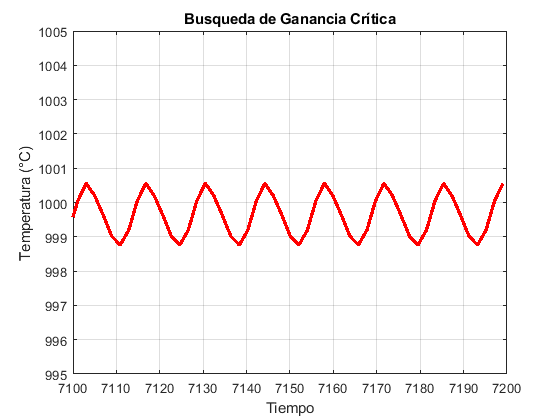

% Calculando constantes
B_1 = (e_p*sigma*A_p*dt)/C_p;
B_2 = (h_aip*A_p*dt)/C_p;
B_3 = (h_aiw*A_int*dt)/C_a;
B_4 = (h_aip*A_p*dt)/C_a;
B_5 = dt/C_w;
B_6 = (h_aiw*A_int*dt)/C_w;
B_7 = (e_p*sigma*A_p*dt)/C_w;
B_8 = dt/(C_w*R_i_f);
B_9 = dt/(C_f*R_i_f);
B_10 = dt/(C_f*R_f_la);
B_11 = dt/(C_la*R_f_la);
B_12 = dt/(C_la*R_la_lb);
B_13 = dt/(C_lb*R_la_lb);
B_14 = dt/(C_lb*R_lb_lc);
B_15 = dt/(C_lc*R_lb_lc);
B_16 = dt/(C_lc*R_lc_e);
B_17 = (e_t*sigma*A_t*dt)/C_t;
B_18 = (h_aip*A_t*dt)/C_t;

%exp_table = readtable('Datos_N_50.csv');
%temp_exp = table2array(exp_table(:, 2))';
%time_exp = table2array(exp_table(:, 1))';

P_max = 2500;        % Potencia MÁXIMA del calefactor (W)
SP_C = 1000;          % Setpoint (Temperatura Objetivo) en Celsius (°C)
SP_K = SP_C + 273.15;% Setpoint en Kelvin (K)

% Variables de estado del PID
MV = 0;              % Variable Manipulada (Salida PID, 0 a 1)
e_k = 0;             % Error actual
e_k1 = 0;            % Error en (k-1)
e_k2 = 0;            % Error en (k-2)
MV_k1 = 0;           % Salida PID en (k-1)

t_max = 7200;        % Tiempo total de simulación (s) (50 minutos)
n_steps = t_max / dt;% Número de pasos
T_amb = 15 + 273.15; % Temperatura ambiente (K)

t = 0:dt:t_max;

T_t = zeros(1, length(t));
T_p = zeros(1, length(t)); 
T_a = zeros(1, length(t)); 
T_i = zeros(1, length(t));
T_f = zeros(1, length(t));
T_la = zeros(1, length(t));
T_lb = zeros(1, length(t));
T_lc = zeros(1, length(t));

% Condiciones iniciales
T_t(1) = T_amb;
T_i(1) = T_amb;
T_p(1) = T_amb;
T_a(1) = T_amb;
T_f(1) = T_amb;
T_la(1) = T_amb;
T_lb(1) = T_amb;
T_lc(1) = T_amb;

Q = [];
% Ganancias PID 
Kp = 0.42;            
Ki = 0;          
Kd = 0;
% Bucle principal de cálculos
for k = 1:n_steps
    % Obtener temperaturas del paso anterior (k)
    T_t_k = T_t(k);
    T_i_k = T_i(k); 
    T_p_k = T_p(k);
    T_a_k = T_a(k);
    T_f_k = T_f(k);
    T_la_k = T_la(k);
    T_lb_k = T_lb(k);
    T_lc_k = T_lc(k);
    
    % 1. Medir la Variable de Proceso (PV)
    PV_K = T_t_k; 
    
    % 2. Calcular el Error actual
    e_k = SP_K - PV_K;
    
    % 3. Calcular la Salida (Forma de Posición P-Only)
    % ¡ESTA ES LA LÍNEA CLAVE!
    % La salida MV es DIRECTAMENTE proporcional al error.
    MV = Kp * e_k;
    % 4. Saturar la Salida del Controlador (MV)
    if MV > 1.0
        MV = 1.0;  % Saturar a 100% potencia
    elseif MV < 0.0
        MV = 0.0;  % Saturar a 0% potencia
    end
    
    % 5. Calcular la Potencia de Entrada REAL
    Q_in = MV * P_max;
    Q(k) = Q_in;
    
    % --- Calcular las temperaturas en los nodos a través de las paredes (Q_dot) ---
    T_t(k+1) = T_t_k + B_17*(T_i_k^4-T_t_k^4) + B_18*(T_a_k-T_t_k);
    T_p(k+1) = T_p_k + B_1*(T_i_k^4-T_p_k^4) + B_2*(T_a_k-T_p_k);
    T_a(k+1) = T_a_k + B_3*(T_i_k-T_a_k) - B_4*(T_a_k-T_a_k);
    T_i(k+1) = T_i_k + B_5*Q_in - B_6*(T_i_k-T_a_k) - B_7*(T_i_k^4-T_p_k^4) - B_8*(T_i_k-T_f_k);
    T_f(k+1) = T_f_k + B_9*(T_i_k-T_f_k) - B_10*(T_f_k-T_la_k);
    T_la(k+1) = T_la_k + B_11*(T_f_k-T_la_k) - B_12*(T_la_k-T_lb_k);
    T_lb(k+1) = T_lb_k + B_13*(T_la_k-T_lb_k) - B_14*(T_lb_k-T_lc_k);
    T_lc(k+1) = T_lc_k + B_15*(T_lb_k-T_lc_k) - B_16*(T_lc_k-T_amb);
end

figure;
% subplot(2,1,1); % Gráfico superior para las temperaturas internas
% hold on;
% plot(time_exp, temp_exp, 'c-', 'LineWidth', 2);  % Carcasa
% title('Simulación FDM (6 Nodos) - Temperaturas Internas');
% xlabel('Tiempo');
% ylabel('Temperatura (°C)');
% ylim([15 25]);
% xlim([0 50]);
% legend('T_{Exp}', 'Location', 'SouthEast');
% grid on;
% box on;
% 
% subplot(2,1,2); % Gráfico inferior para la pared
hold on;
plot(t, T_t - 273.15, 'r-', 'LineWidth', 2.5); % Cara interna
%plot(t, T_a - 273.15, 'm-', 'LineWidth', 2); % Aire
%plot(t, T_p - 273.15, 'g-', 'LineWidth', 2);  % Pieza
%plot(t, T_f - 273.15, 'b--', 'LineWidth', 2);  % fibra
%plot(t, T_la - 273.15, 'g--', 'LineWidth', 2);  % lana
%plot(t, T_lb - 273.15, 'm--', 'LineWidth', 2);  % lana
%plot(t, T_lc - 273.15, 'm--', 'LineWidth', 2);  % exterior
title('Busqueda de Ganancia Crítica');
xlabel('Tiempo');
ylabel('Temperatura (°C)');
xlim([7100 7200]);
ylim([995 1005]);
%legend('T_{termocupla}', 'T_{aire}', 'T_{pieza}', 'T_{fibra}', 'T_{lana_1}', 'T_{lana_2}', 'T_{ext}','Location', 'SouthEast');
grid on;
box on;
hold off;